# State Estimation

## Objectives

- Introduction to IMU (Gyro,acc, mag) and how to simulate it

- Formulate an Extended Kalman Filter for attitude estimation of a drone

- Some guidlines to tune the EKF and analyze its performance

- Simulation of sensors in Simulink

- Simulation of EKF in Simulink

## Prerequistes

- This unit builds upon the previous units (attitude representation and control, position control), hence knowledge from the previous units is required

- Understand how IMU works, here are some videos that are useful:

-  gyroscopes: [https://robotacademy.net.au/lesson/how-gyroscopes-work/](https://robotacademy.net.au/lesson/how-gyroscopes-work/)

- accelerometers: [https://robotacademy.net.au/lesson/using-accelerometers/](https://robotacademy.net.au/lesson/using-accelerometers/)

- magnetometers: [https://robotacademy.net.au/lesson/using-magnetometers/](https://robotacademy.net.au/lesson/using-magnetometers/)

# Inertial Measurement Unit (IMU) modeling

**Notes:**

- Some aspects of modeling the sensors are ignored since they are not crucial to basic simulations. 

- Sensor dynamics are not discussed, this includes things like sensor bandwidth.

- Raw sensor data are usually preprocessed and filtered before any use, we don't discuss the filtering aspect. Filters are included in our simulation though.

## Gyroscope

Gyros measure angular acceleration in body frame, usually called body rates p,q,r. It is quite easy to simulate gyros, we will need the ground truth angular velocity in body frame then add bias and noise terms to it. To make it more realistic, we can add coupling and scaling factors as well, but typically these factors are estimated and removed with calibration.

#### 
$${}^b{\omega \;}_{\textrm{gyro}}={}^b{\omega \;}+{\mathit{\mathbf{b}}}_g +\eta_g$$


where 

${}^b{\omega \;}_{\textrm{gyro}}$is angular velocities (rad/s) measured by the gyro

${}^b{\mathit{\mathbf{R}}}_g$is the rotation matrix from world frame to body frame

${}^b{\omega \;}$ is the ground truth angular velocities (rad/s)

${\mathit{\mathbf{b}}}_g ,\;\eta_g$ are the gyro noise and bias terms

For drones, gyros have two big rules:

- Rate control where the rates measured by the gyro are used in the PID feedback to regulate the angular rates ( Acro mode). This is the lowest controller of the drone

- Input to process model of the state estimator, where the gyro readings are converted into quaternion derivative then integrated to update the quaternion (attitude)

The biggest issue with gyro is the drift, gyro accumlates bias overtime. In order to remove this bias, we can use accelerometer (gravity vector pointing down) and magnetometer(magnetic vector pointing north) to correct this bias. And this is the inuition we will use in our EKF formulation

## Accelerometer

accelerometer measures linear acceleration in body frame. Without any movement, it reports zero accelerationx in x,y and gravity value g in z-axis. Accelerometers typically report the values in g unit (multiples of gravity), however we will assume raw values in $\frac{m}{s^2 }$ here.

Accelerometer provides a reference vector pointing down (gravity), we will assume the drone is on average under the effect of gravity only, i.e. no other accelerations. This is valid assuming we average the drone orientation for very long time, this results in a hover state even though there are movements. This assumption will not hold if the drone keeps moving for a long time.

To simulate accelerometer (assuming NED coordinate frame), we need total accelerations in body frame, therefore we need to transform the gravity vector to body frame and add it to the accelerations produced by the drone actuators :

#### 
$${}^b{\mathit{\mathbf{a}}}={}^b{\mathit{\mathbf{R}}}_g*\overrightarrow{\mathit{\mathbf{g}}} -\frac{F_{\textrm{thrust}} }{m}+{\mathit{\mathbf{b}}}_a +\eta_a$$


where 

${}^b{\mathit{\mathbf{a}}}$is  measured acceleration vector in the body frame by the accelerometer

${}^b{\mathit{\mathbf{R}}}_g$is the rotation matrix from world frame to body frame

$\overrightarrow{\mathit{\mathbf{g}}}$ is the reference gravity vector  in the world frame $\left\lbrack \begin{array}{c}
0\\
0\\
g
\end{array}\right\rbrack$

$F_{\textrm{thrust}}$ is the thrust produced by the drone

$m$ is drone weight in kg

${\mathit{\mathbf{b}}}_a ,\;\eta_a$is the magnetometer noise and bias.

## Magnetometer 

The magnetometer sensor measures the magnetic field for all three physical axes (x, y, z) in μT (micro Tesla). It essentially provides a reference vector pointing (magnetic)North. We assume there are no magnetic interferance and the magnetometer has been calibrated to get rid of scaling, bias and Iron factors. You can refer to this link ([https://thepoorengineer.com/en/calibrating-the-magnetometer/](https://thepoorengineer.com/en/calibrating-the-magnetometer/)) for more details about magnetometer error modeling and calibration.

For ease of simulation, let's assume that the drone starts pointing North. The magnetometer will then measure [1,0,0] in NED frame. This value is of course normalized since the raw values are reported in μT. This will help us derive the measurement model and its Jacobian for EKF later.

Our measurement model that we will use in our state estimator measurement model and in our  magnetometer sensor simulation is:

#### 
$${}^b{\mathit{\mathbf{m}}}={}^b{\mathit{\mathbf{R}}}_g*{}^b{\mathit{\mathbf{m}}}_r+{\mathit{\mathbf{b}}}_m +\eta_m$$


where 

${}^bm$is  measured magnetic field in the body frame by the magnetometer

${}^bR_g$is the rotation matrix from world frame to body frame

${}^bm_r$is the reference magnetic North vector in the world frame,  in our case $\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack$

$b_m ,\;\eta_m$is the magnetometer noise and bias.

**Note:**

The magnetometer provides us with a vector that is always pointing to the magnetic North. This vector changes (elevation of the vector changes depending on the altitude) over the surface of the Earth thus we will need a map of the vectors if we want a reference vector that works across the globe.

# Attitude estimation using Extended Kalman Filter - Formulation

## Recall

- Attitude is represented by unit quaternion

- The conversion from quaternion to rotation matrix (world to body) is

syms q0 q1 q2 q3;
C_11  = q1^2 + q0^2 - q2^2 - q3^2;
C_12  = 2*(q1*q2 + q3*q0);
C_13  = 2*(q1*q3 - q2*q0);
C_21  = 2*(q1*q2 - q3*q0);
C_22  = q2^2 + q0^2 - q1^2 - q3^2;
C_23  = 2*(q2*q3 + q1*q0);
C_31  = 2*(q1*q3 + q2*q0);
C_32  = 2*(q2*q3 - q1*q0);
C_33  = q3^2 + q0^2 - q1^2 - q2^2;
bRg = [ C_11, C_12, C_13;
C_21, C_22, C_23;
C_31, C_32, C_33; ];
bRg

$$bRg = \left(\begin{array}{ccc} {q_{0}}^{2}+{q_{1}}^{2}-{q_{2}}^{2}-{q_{3}}^{2} & 2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2} & 2\,q_{1}\,q_{3}-2\,q_{0}\,q_{2}\\ 2\,q_{1}\,q_{2}-2\,q_{0}\,q_{3} & {q_{0}}^{2}-{q_{1}}^{2}+{q_{2}}^{2}-{q_{3}}^{2} & 2\,q_{0}\,q_{1}+2\,q_{2}\,q_{3}\\ 2\,q_{0}\,q_{2}+2\,q_{1}\,q_{3} & 2\,q_{2}\,q_{3}-2\,q_{0}\,q_{1} & {q_{0}}^{2}-{q_{1}}^{2}-{q_{2}}^{2}+{q_{3}}^{2} \end{array}\right)$$

We are going to focous on using EKF algorithm to estimate the attitude based on data coming from IMU unit (Gyro+Accelometer+Magnetometer).

The same EKF algorithm can also be used to estimate local position or even estimate both attitude and local position. For example PX4 uses a 24-state vector EKF to estimate various parameters [https://docs.px4.io/main/en/advanced_config/tuning_the_ecl_ekf.html](https://docs.px4.io/main/en/advanced_config/tuning_the_ecl_ekf.html).

Our focus here is not to explain in details how kalman filters work and how to implement its equations, we rather focus on how to use these filters for certain application. 

In order to use EKF ,or any other estimator for that matter, we need two models:

- **Process model** that descibe how the next state is related to the previous state

- **Measurement model **that describes how the current measurement is related to the current state (prior).

The procedure to apply EKF is summarized in these steps, which we will be following:

- **Define the state vector**

- **Formulate the process model** and descritize it. In case of Kalman filter you will also need to linearize it if it is nonlinear.

- **Formulate the measurement model **and descritize it, in case of Kalman filter you will also need to linearize it if it is nonlinear.

- **Calculate Jacobian **of process and measurement models (for EKF)

- **Define the process and measurement variances (Q, R), initial covariance **$P_0$**, and initial state **${\mathit{\mathbf{x}}}_0$.

- **Tune the filter (P,Q,**$P_0$**, **${\mathit{\mathbf{x}}}_0$**) and analyze its performance**

Let's define our filter states as the quaternion attitude and the gyro bias


$$x=\left\lbrack \begin{array}{c}
q_0 \\
q_1 \\
q_2 \\
q_3 \\
{}^gb_1\\
{}^gb_2\\
{}^gb_3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\tilde{\mathit{\mathbf{q}}} \\
{}^g{\tilde{\mathit{\mathbf{b}}} }
\end{array}\right\rbrack$$


## **Process model: **

- also called state transition function.

- This shows how to use previous state (and probably other inputs) to predict next state

- For example we can use previous position and velocity to predict next position $x\left\lbrack t\right\rbrack =x\left\lbrack t-1\right\rbrack +\textrm{dt}*v\left\lbrack k-1\right\rbrack$

- In our case, we use the quaternion derivative formula (discussed in previous units) as follows:

where

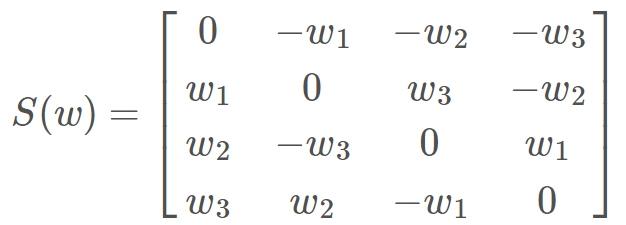       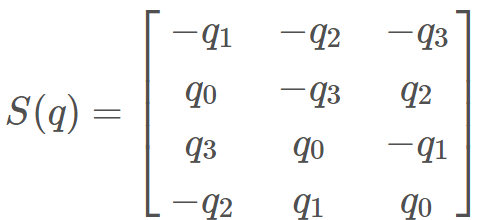

- This formulate requires additional input besides the state, angular velocity. We can use gyro measurements for this. However since gyro drifts overtime, we can remove the bias using the bias in the state vector. After all, that is why we added gyro bias to our state vector. The result will be:

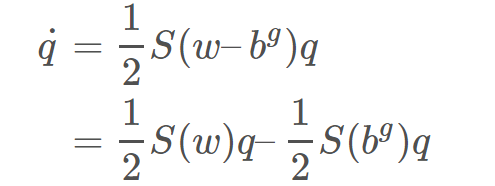

- Next, we will need to discretize the above equation so that we can implement it in discrete time. Use the first order linearized model to make things simpler. Therefore,

 

where T is the update time

- So our final process model equation will be:

- Ths previous equation represents the process model for the quaternion (first four states). For the gyro bias vector, we assume a constant bias model. This doesn't mean the bias will be constant since EKF alters the states of the equation thus the value of the bias actually changes over time when we actually implement the algorithm.. The complete system state equation can be written as follows.

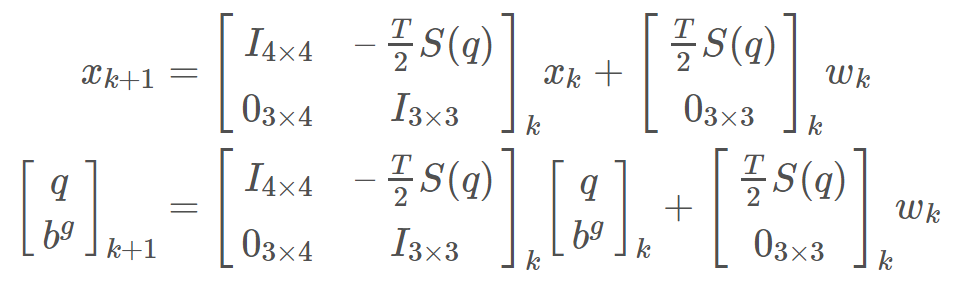

### Process model jacobian

From previous equations, it is easy to get the Jacobian matrix A (also called F). It is actually the matrix that we multiply by state vector

#### 
$$A=\left\lbrack \begin{array}{cc}
I_{4\times 4}  & -\frac{T}{2}S\left(q\right)\\
0_{3\times 4}  & I_{3\times 3} 
\end{array}\right\rbrack$$


## Meaurement Model:

We will use the accelerometer and magnetometer data as our measurements so we will have a measurement vector $z$ of size 6.  Let's use our previous modeling of these sensors to formulate the measurement model. We will handle one at a time then combine them in one system.

### Accelerometer

from previous model

#### 
$${}^b{\mathit{\mathbf{a}}}={}^b{\mathit{\mathbf{R}}}_g*\overrightarrow{\mathit{\mathbf{g}}} -\frac{F_{\textrm{thrust}} }{m}+{\mathit{\mathbf{b}}}_a +\eta_a$$


Let's assume that external forces are negligible and the only force that acts on the body is the gravitational force. This is valid when we average the accelerations for long time since the drone will most of the time be in hover state. Without this assumption, we can't easily formulate the measurement model. As a result of this assumption, we will also increase the measurement variance of accelerometer as we will see later. 

Now, if we know the orientation of the body, we can predict the acceleration that the accelerometer is going to measure (taking into account previous assumption). The measurement model becomes:

#### 
$${}^b{\mathit{\mathbf{a}}}={}^b{\mathit{\mathbf{R}}}_g*\overrightarrow{\mathit{\mathbf{g}}} +{\mathit{\mathbf{b}}}_a +\eta_a$$


**Notes:** 

- The reason we develop measurement model to predict measurements is for EKF to use this prediction to compare with the actual measured acceleration to determine the error in our orientation. The Extended Kalman Filter (EKF) will then automatically help us convert this error into the bias term of the gyrometer. 

- Thenoise and bias terms are ignored in our implementation of measurement model since we assume they are additive (valid assumption for IMU).

Let's code the accelerometer measurement model:

syms eta_a b_a g
G = [0;0;g]; % gravity vector
a = bRg*G+eta_a+b_a

$$a = \left(\begin{array}{c} b_{a}+\eta_{a}-g\,\left(2\,q_{0}\,q_{2}-2\,q_{1}\,q_{3}\right)\\ b_{a}+\eta_{a}+g\,\left(2\,q_{0}\,q_{1}+2\,q_{2}\,q_{3}\right)\\ b_{a}+\eta_{a}+g\,\left({q_{0}}^{2}-{q_{1}}^{2}-{q_{2}}^{2}+{q_{3}}^{2}\right) \end{array}\right)$$

We can see that the measurement model is nonlinear (square terms) due to the use of rotation matrix, hence the use of EKF instread of Kalman Filter for our application.

#### Accelerometer model jacobian

We require Jacobian of the sensor measurement model as part of the EKF state estimator.  Let's  take the jacobian of the previous measurement model with respect to quaternion.

h_acc = jacobian(a,[q0,q1,q2,q3])

$$h\_acc = \left(\begin{array}{cccc} -2\,g\,q_{2} & 2\,g\,q_{3} & -2\,g\,q_{0} & 2\,g\,q_{1}\\ 2\,g\,q_{1} & 2\,g\,q_{0} & 2\,g\,q_{3} & 2\,g\,q_{2}\\ 2\,g\,q_{0} & -2\,g\,q_{1} & -2\,g\,q_{2} & 2\,g\,q_{3} \end{array}\right)$$

of course in our case we need to extend Jacobian to the remaining state vector, i.e. the gyro bias. But the result will be zeros. 

### Magnetometer

We will use the same model we developed previously for the magnetometer measurement model :

#### 
$${}^b{\mathit{\mathbf{m}}}={}^b{\mathit{\mathbf{R}}}_g*{}^b{\mathit{\mathbf{m}}}_r+{\mathit{\mathbf{b}}}_m +\eta_m$$


Let's code this model

syms eta_m b_m
Mr = [1;0;0]; % reference magnetic field
M = bRg*Mr+eta_m+b_m

$$M = \left(\begin{array}{c} {q_{0}}^{2}+{q_{1}}^{2}-{q_{2}}^{2}-{q_{3}}^{2}+b_{m}+\eta_{m}\\ b_{m}+\eta_{m}-2\,q_{0}\,q_{3}+2\,q_{1}\,q_{2}\\ b_{m}+\eta_{m}+2\,q_{0}\,q_{2}+2\,q_{1}\,q_{3} \end{array}\right)$$

We also observe a nonlinear measurement model here as well  and that is also due to the use of rotation matrix. That is another justification for the use of EKF rather than linear Kalman filter.

#### Magnetometer model jacobian

We require Jacobian of sensor measurement model as part of the EKF state estimator (of course we can also perform this numerically but that will be less efficient).  Let's  take the jacobian of the previous measurement model with respect to quaternion.

h_mag = jacobian(M,[q0,q1,q2,q3])

$$h\_mag = \left(\begin{array}{cccc} 2\,q_{0} & 2\,q_{1} & -2\,q_{2} & -2\,q_{3}\\ -2\,q_{3} & 2\,q_{2} & 2\,q_{1} & -2\,q_{0}\\ 2\,q_{2} & 2\,q_{3} & 2\,q_{0} & 2\,q_{1} \end{array}\right)$$

of course in our case we need to extend Jacobian to the remaining state vector, i.e. the gyro bias. But the result will be zeros. 

### Complete measurement model and Jacobian

Combining the accelerometer and Magnetometer models, our final measurement model is

#### 
$$\overrightarrow{\mathit{\mathbf{z}}} =\left\lbrack \begin{array}{c}
\mathit{\mathbf{a}}\\
\mathit{\mathbf{m}}
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{}^b{\mathit{\mathbf{R}}}_g*\overrightarrow{\mathit{\mathbf{g}}} \\
{}^b{\mathit{\mathbf{R}}}_g*{}^b{\mathit{\mathbf{m}}}_r
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
\eta_a \\
\eta_m 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
{\mathit{\mathbf{b}}}_a \\
{\mathit{\mathbf{b}}}_m 
\end{array}\right\rbrack$$


And the Jacobian **H** of this model is:

H = [
    h_acc  zeros(3);
    h_mag  zeros(3);
]

$$H = \left(\begin{array}{ccccccc} -2\,g\,q_{2} & 2\,g\,q_{3} & -2\,g\,q_{0} & 2\,g\,q_{1} & 0 & 0 & 0\\ 2\,g\,q_{1} & 2\,g\,q_{0} & 2\,g\,q_{3} & 2\,g\,q_{2} & 0 & 0 & 0\\ 2\,g\,q_{0} & -2\,g\,q_{1} & -2\,g\,q_{2} & 2\,g\,q_{3} & 0 & 0 & 0\\ 2\,q_{0} & 2\,q_{1} & -2\,q_{2} & -2\,q_{3} & 0 & 0 & 0\\ -2\,q_{3} & 2\,q_{2} & 2\,q_{1} & -2\,q_{0} & 0 & 0 & 0\\ 2\,q_{2} & 2\,q_{3} & 2\,q_{0} & 2\,q_{1} & 0 & 0 & 0 \end{array}\right)$$

**Note: ** the 3by6 zero matrix added is representing the gyro bias since our state vector is composed of quaternion+gyro bias

# Extended Kalman Filter -  operations 

After formulating the required models to apply EKF, let's briefly go through how EKF works and the equations it uses.

EKF is a recursive algorithm that performs two operations: Predict >> Update. 

- **predict step**: uses our developed process model and previous state to predict the current state (called priori estimate). It also updates the covariance P (how much we trust this priori estimate).

- **Update step: ** uses the developed measurement model along with current measurements from sensors to calculate innovation (how much the measurements differ from our predicted measurements using the measurement model). It will also calculate the kalman gain. Using the innovation and kalman gain, the EKF will then update the current state estimate (called posteri estimate). It is essentially doing a weighted average between measurements and predictions from process model and the weight is dynamically changing depending on the covariance matrix P. Finally the covariance matrix P is also updated (posteri estimate of covariance).

Let's detail the equations of these steps:

## Prediction

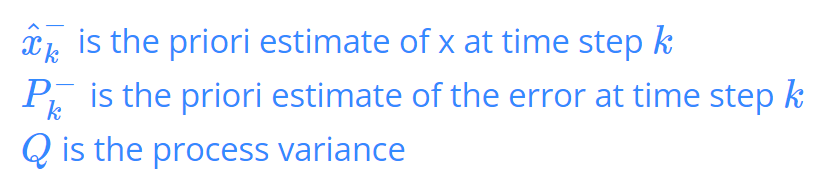

From our process model we can see that 

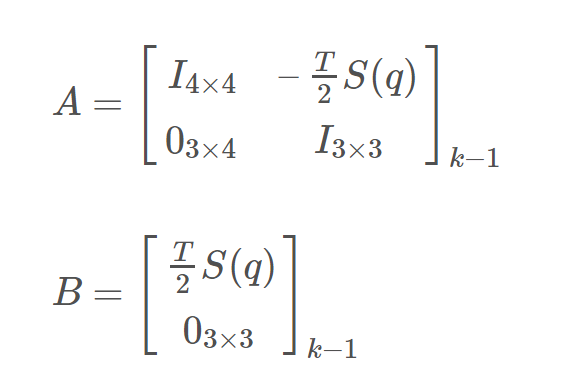

We need to define the initial covariance matrix **P **and define the **Q** process variance matrix.

We need to experiment with **P** value to get the desired performance. If we start with a **P** matrix with huge values, it may not converge to give you a coherent result. On the other hand, if we start with a** P** matrix with small values, it may take quite a while for the **P** matrix to converge to the actual solution. 

The **Q** matrix represents the inaccuracies of the process model that we are using.

## Update

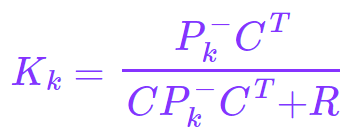

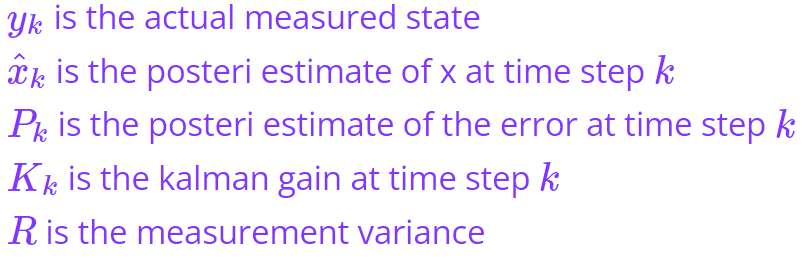

**C** (or in our notation **H**) matrix is a matrix to convert our filter states to the measured variables.  in our case, our measured variables are the direction of the gravity and North vector while our filter states are the quartenion and the gyro bias. They are essentially different parameters thus we have to figure out a **C** matrix which allows us to convert out state variables into the measured variables. This is actually our measurement model Jacobian matrix (H) we developed earlier.

#### 
$$\overrightarrow{\mathit{\mathbf{z}}} =C{\hat{x} }_k^- =H{\hat{x} }_k^- =\left\lbrack \begin{array}{c}
H_{\textrm{acc}} \\
H_{\textrm{mag}} 
\end{array}\right\rbrack$$


**R** is the measurement variance and it represents how accurate our measurement data is. Similar to the **Q** matrix in equation, this term is important yet difficult to determine. The values of these terms are usually determined through simulations or actual tests.

$y_k$ is the actual measurement values that we obtain from the sensor data $y_k =\left\lbrack \begin{array}{c}
a_m \\
m
\end{array}\right\rbrack$

# Simulation

Assumptions:

- Reference gravity vector [0,0,g]

- Refernce mag vector after calibration and the drone is aligned with North [1,0,0]

- Previous reference vectors are used to simulate the sensors as well as derive the measurement model and jacobian, any changes to them should be followed by updates to these models as well.

- We use our previous drone model which also includes control blocks

- Ensure you are inside the folder where this live script is (*4_state_estimation*)

Let's load our simulation parameters:

clear all;
run("quad_params_ekf.m")

## Sensor Simulation

Let's first simulate the sensors and see how sensor inaccuracies result in drifts when we use them directly to calculate attitude or position.

The sensors are simulated with the following biases

IMU.accBias

ans =     0.0900   -0.0600    0.3370


IMU.gyroBias

ans =    -0.0095   -0.0075    0.0015


IMU.magBias

ans =     0.0095    0.0075    0.0015


We assume after calibration we get the following biases

IMU.accBiasEst

ans =     0.0800   -0.0500    0.4000


IMU.gyroBiasEst

ans =      0     0     0


IMU.magBiasEst

ans =     0.0050    0.0080    0.0020


open_system("one_sensor_simulation.slx")

There are scopes in the simulation to compare ground truth of body accelerations and angular velocities to those measured by sensors (after filtering and processing). Here is a comparison of Z-axis acceleration measured by accelerometer (gravity is removed) vs actual acceleration. You can see unmodeled accelerations such as from coriolis forces.

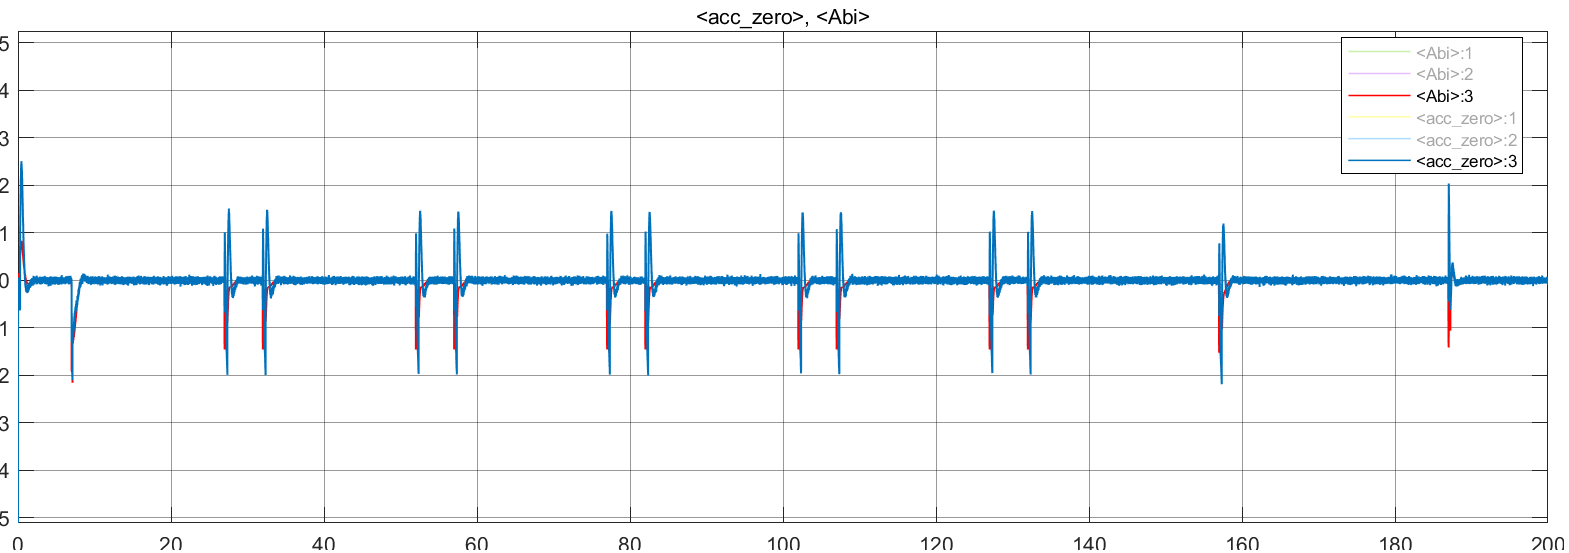

Now let's see what happens if we use the sensors to calculate attitude . We can observe starting very good but drifting overtime

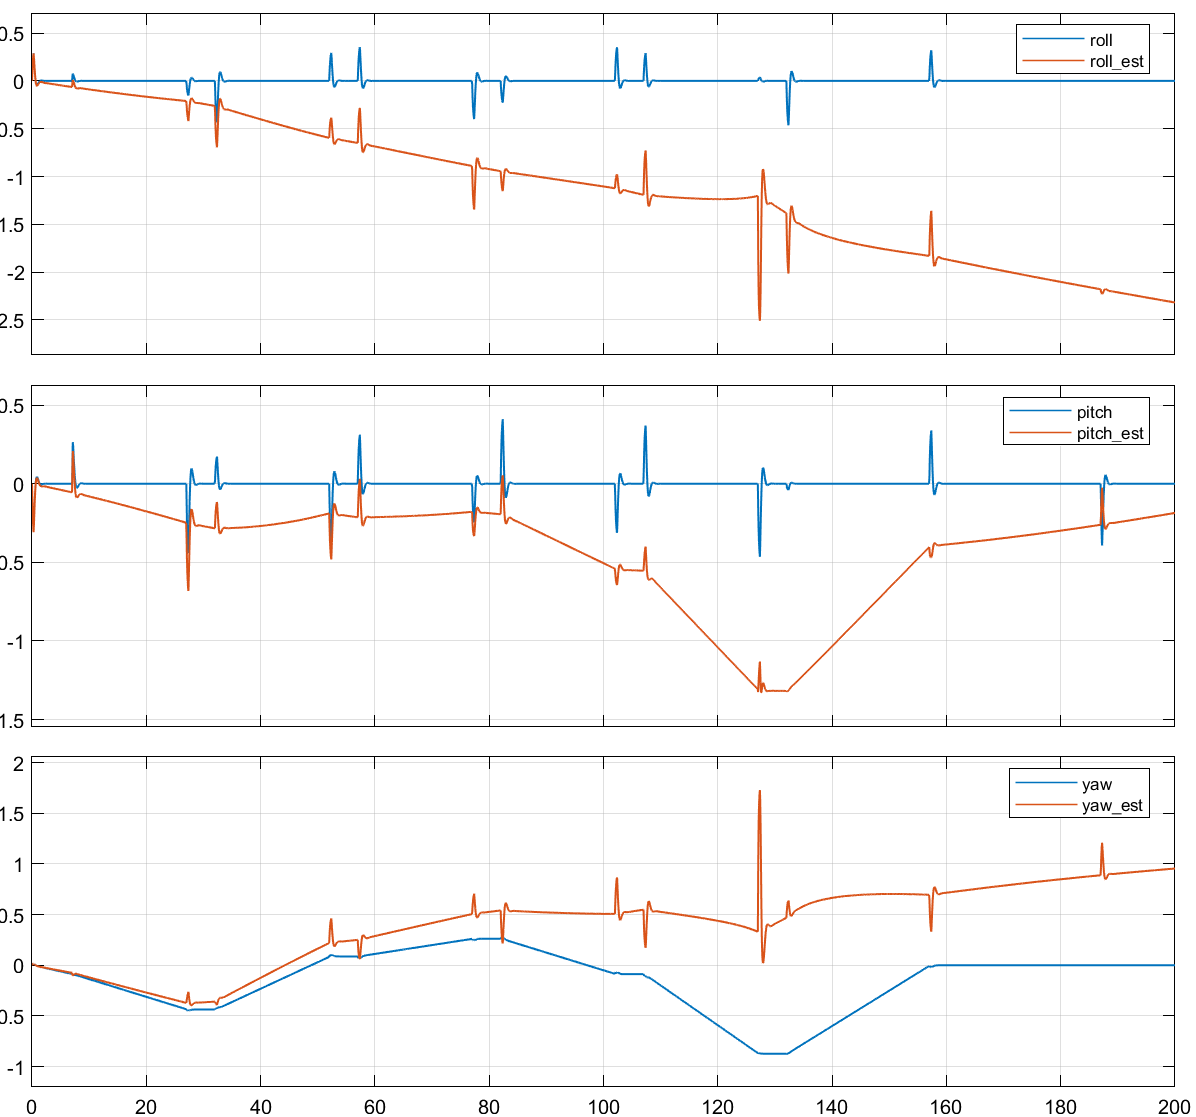

The same happens with position if we use orientation above and acceleration from accelerometer

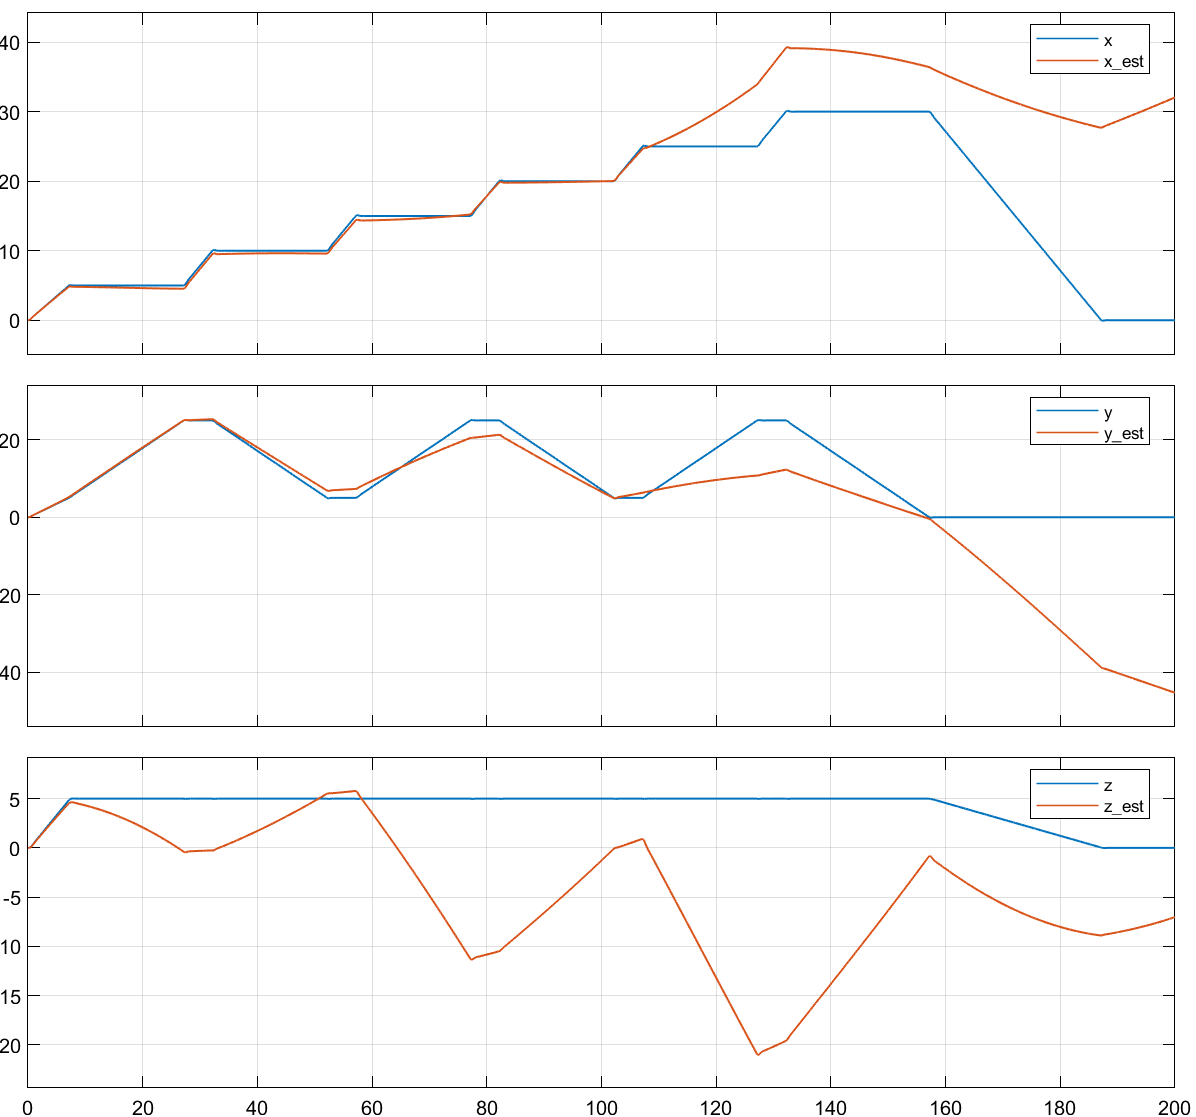

## EKF Simulation

Let's now  simulate the EKF and compare attitude from EKF to ground truth. We can also compare to attitude using sensors without EKF and see how it drifts just like in the previous simulation.

We will use the same sensor parameters as in the last simulation.

open_system("Two_Attitude_Estimation_ekf.slx")

There are many scopes in the simulation to visualize many aspects and compare using EKF to raw data to determine attitude. We can observe with EKF, the attitude estimate is quite accurate and doesn't drift overtime.

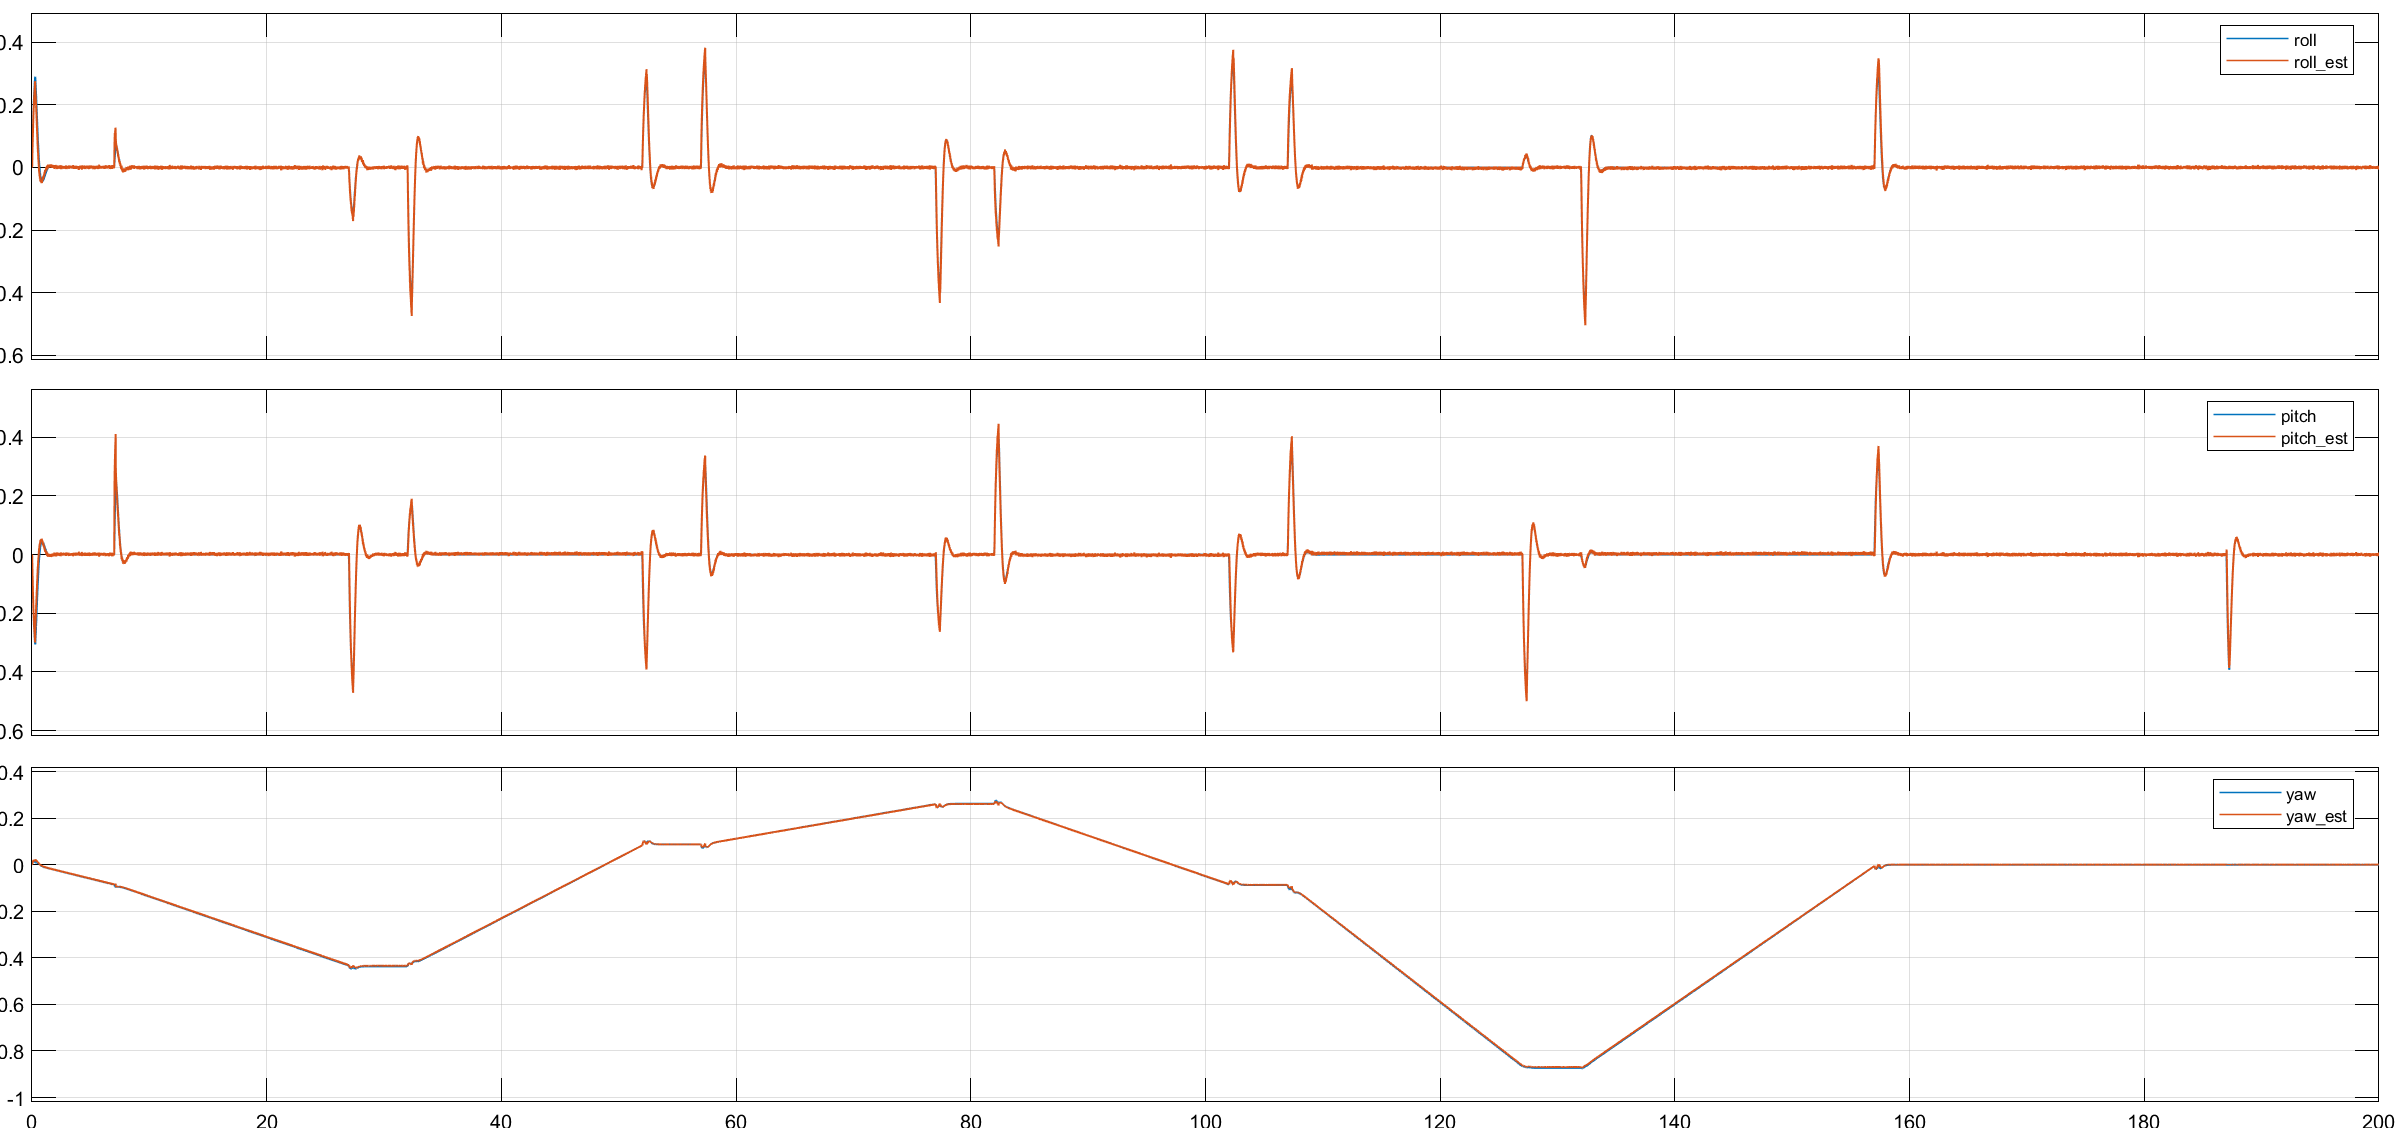

## EKF performance

### Innovation

Innovation is a measure of how much the sensor measurements z differ from the predicted measurement using measurement model H and prior estimate of state. The bigger the difference, the worse the EKF performs. Innovation should be bound and decrease over time.

#### 
$$V\;=\;\;\;y_k -{{\mathrm{Hx}}^- }_k \;\;\;\mathrm{or}\;\;\;y_k -{{\mathrm{Cx}}^- }_k$$


### Innovation covariance S

Innovation covariance (S) is calculated as follows ( part of the EKF gain equation).

#### 
$$S\;=\;\;\;{{\textrm{CP}}^- }_k C^T +R$$


A very good way to analyze EKF performance is to plot each innovation (V) along with its innovation standard deviation ($\sqrt{S}$). This will give very good indication of EKF performance and wether variance tuning is required. Good performance means innovation is bounded between the standard deviation. Below are innovations and std of the EKF. 

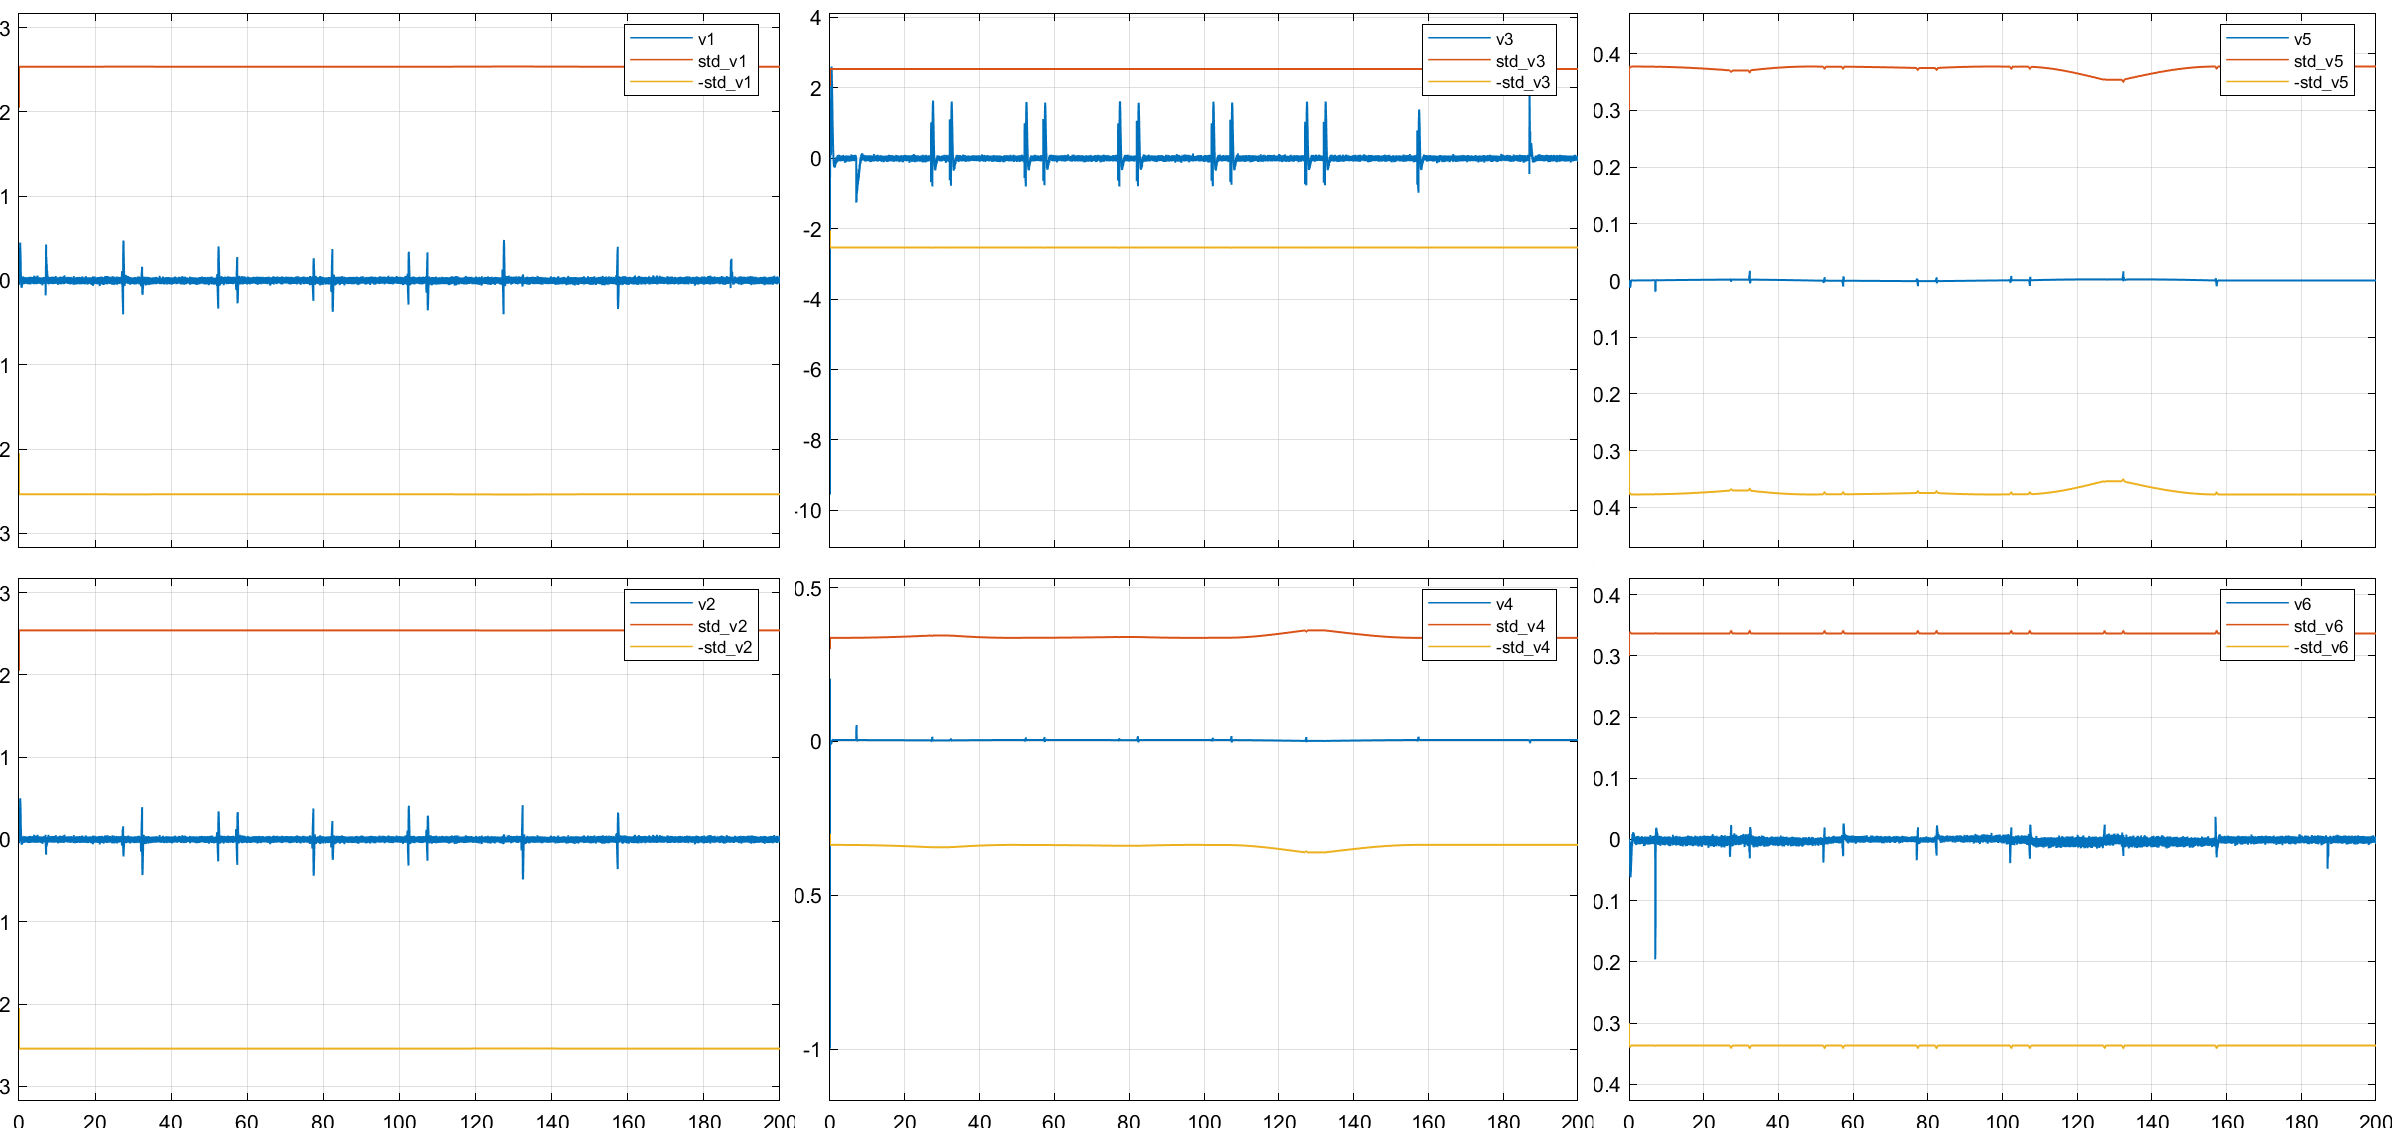

### Orientation error

We can calculate the distance (error) between ground truth and estimated attitude (Quaternion). The EKF estimate has an average value of 0.25 degrees and is plotted below 

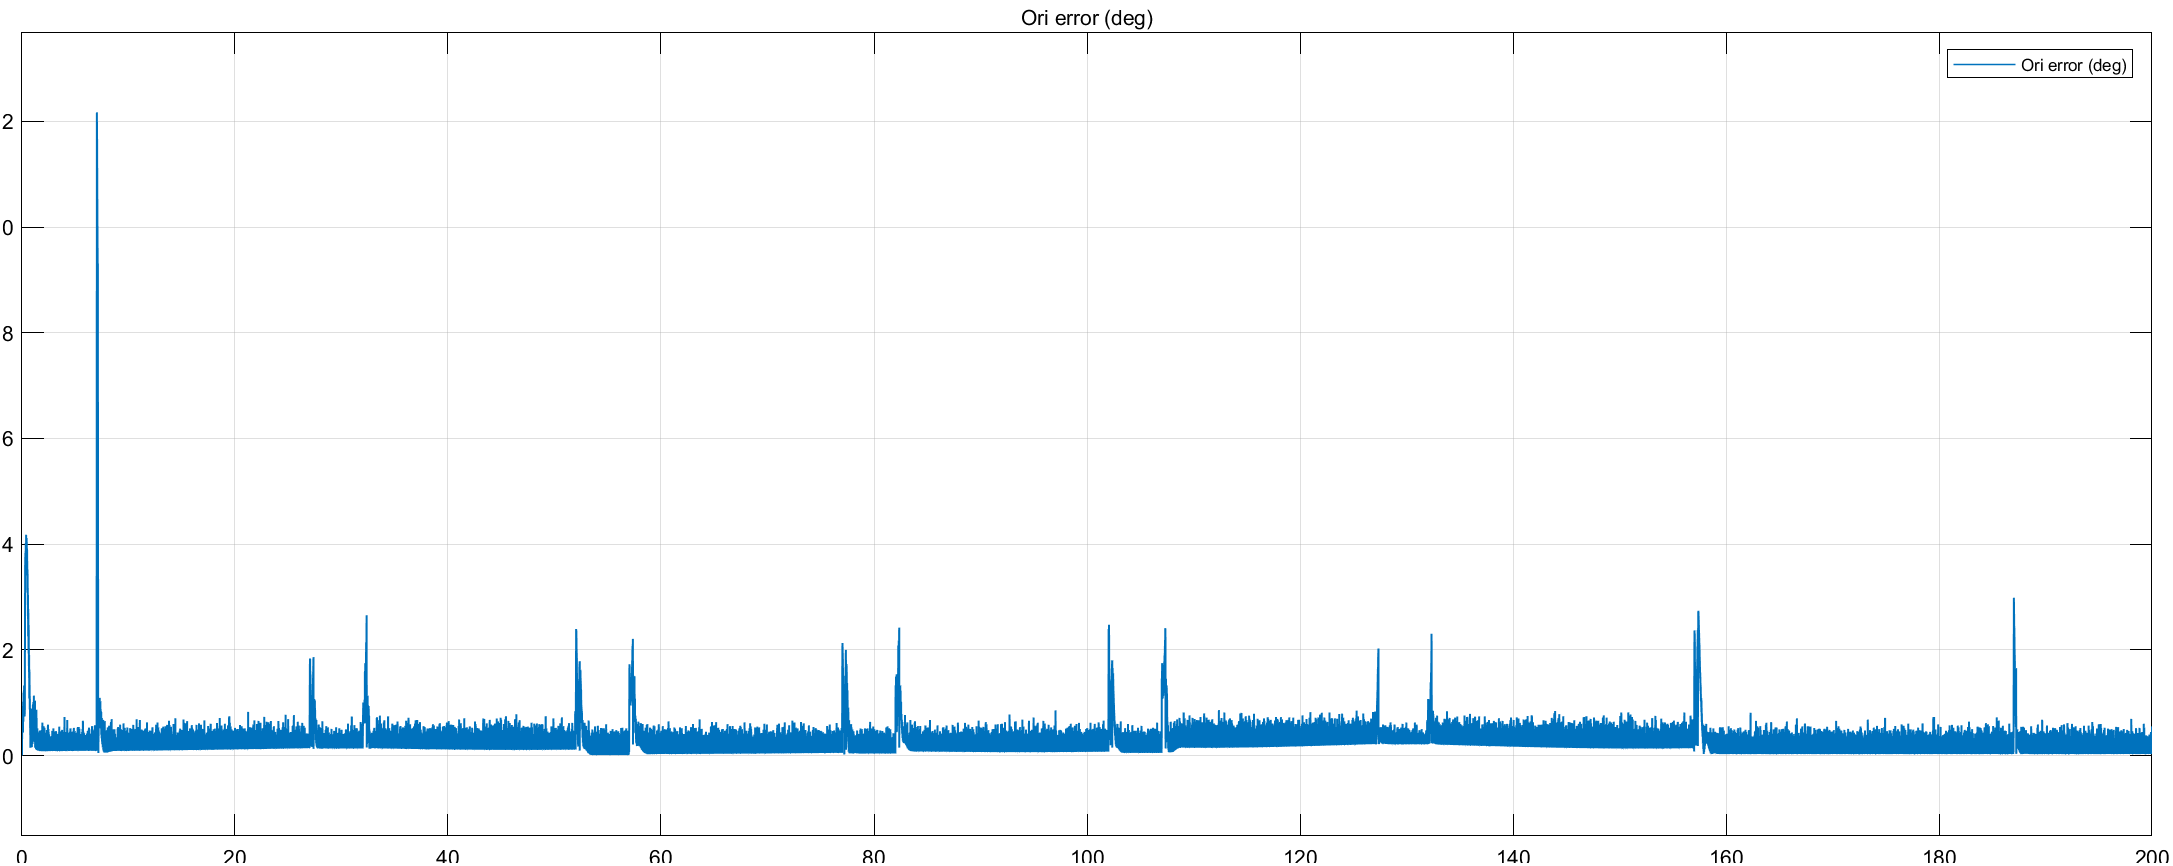

# References:

- magnetometer-calibration: [https://teslabs.com/articles/magnetometer-calibration/](https://teslabs.com/articles/magnetometer-calibration/)

- [https://thepoorengineer.com/en/ekf-impl/#KalmanStates](https://thepoorengineer.com/en/ekf-impl/#KalmanStates)

- [https://www.mathworks.com/help/ident/ref/ekf_block.html](https://www.mathworks.com/help/ident/ref/ekf_block.html)

- How IMU is simulated in Matlab and simulink:

-     [https://www.mathworks.com/help/nav/ref/imu.html#block_IMU_sep_mw_d5f0bdf4-2696-45be-a84f-d27e5aadc478_head](https://www.mathworks.com/help/nav/ref/imu.html#block_IMU_sep_mw_d5f0bdf4-2696-45be-a84f-d27e5aadc478_head)

-     [https://www.mathworks.com/help/nav/ref/imusensor-system-object.html#mw_d780d88c-d3b3-4716-9bd9-c15924e70444](https://www.mathworks.com/help/nav/ref/imusensor-system-object.html#mw_d780d88c-d3b3-4716-9bd9-c15924e70444)